filename = 'resistordata.csv'; % Include the path to the file or use addpath
% Detect the variable types and change them to what you want (mostly to get categorical variables instead of cells of strings)
opts = detectImportOptions(filename);
opts.VariableTypes = {'double','double','double'};

resistors = readtable(filename,opts); %actually read the data
% Get some details about the data
resistors.Properties.VariableNames

ans = 1×3 cell array
    'Year'    'Package'    'Value'


summary(resistors)


Variables:

    Year: 1232×1 double

        Values:

            Min       2012  
            Median    2014  
            Max       2017  

    Package: 1232×1 double

        Values:

            Min          1     
            Median    77.5     
            Max        154     

    Value: 1232×1 double

        Values:

            Min       9195.6 
            Median    9943.7 
            Max        10104 



## Trend over time

Do the resistances measured trend significantly over time? Qualitatively and quantitatively analyze the relationship between measurement year and resistor value.

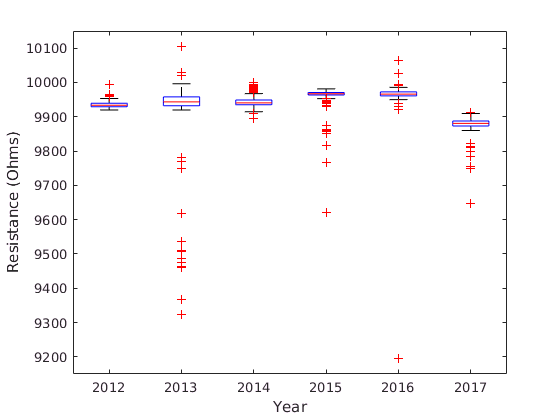

boxplot(resistors.Value,resistors.Year)
xlabel('Year')
ylabel('Resistance (Ohms)')


corrcoef(resistors.Value, resistors.Year)

ans =     1.0000   -0.0867
   -0.0867    1.0000


Speculate on whether it is more appropriate to treat year as a Nominal, Ordinal, Interval, or Ratio value for this analysis.

## Variation within each package

Each resistor comes in a "package" of 8. How does the distribution of resistor values within one package compare to the distribution within an entire year of data?

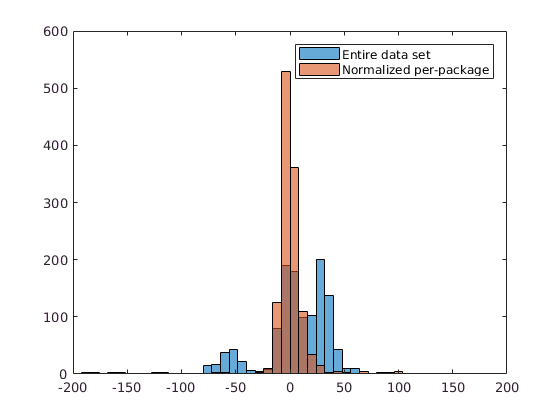

means = [];
for i=1:height(resistors)/8
    means(i)=mean(resistors.Value(resistors.Package==i));
end

h1=histogram(resistors.Value-mean(resistors.Value),'NumBins',50,'BinLimits',[-200,200]);

hold on
normalized = [];
for i=1:height(resistors)
    normalized(i)=resistors{i,3}-means(resistors{i,2});
end

h2=histogram(normalized,'NumBins',50,'BinLimits',[-200,200]);
hold off
legend('Entire data set', 'Normalized per-package')